# Chapter 07: Clustering

close all; clear all;

% generate clustered data to test single-linkage clustering and center-based clustering
rng(13)                           % comment out this line to generate a different dataset
k = 5;                            % number of clusters
M = randi(25,1,k);                % numbers of datapoints per cluster
m = sum(M);                       % total number of datapoints
X = [];                           % dxm matrix to hold the datapoints (d=3)
for h = 1:k
    center_h = [cos(2*pi/k*h); sin(2*pi/k*h); .05*rand];  
    radius_h = rand/k;
    X_h = [center_h(1) + radius_h*randn(1,M(h));...
           center_h(2) + radius_h*randn(1,M(h));
           center_h(3) + .05*randn(1,M(h))];
    X = [X X_h];
end
% shuffle the datapoints
X = X(:,randperm(m));            
% store all pairwise distances into a matrix
dist = zeros(m,m);
for i=1:m
    for j=1:m
        dist(i,j) = norm(X(:,i)-X(:,j));
    end
end

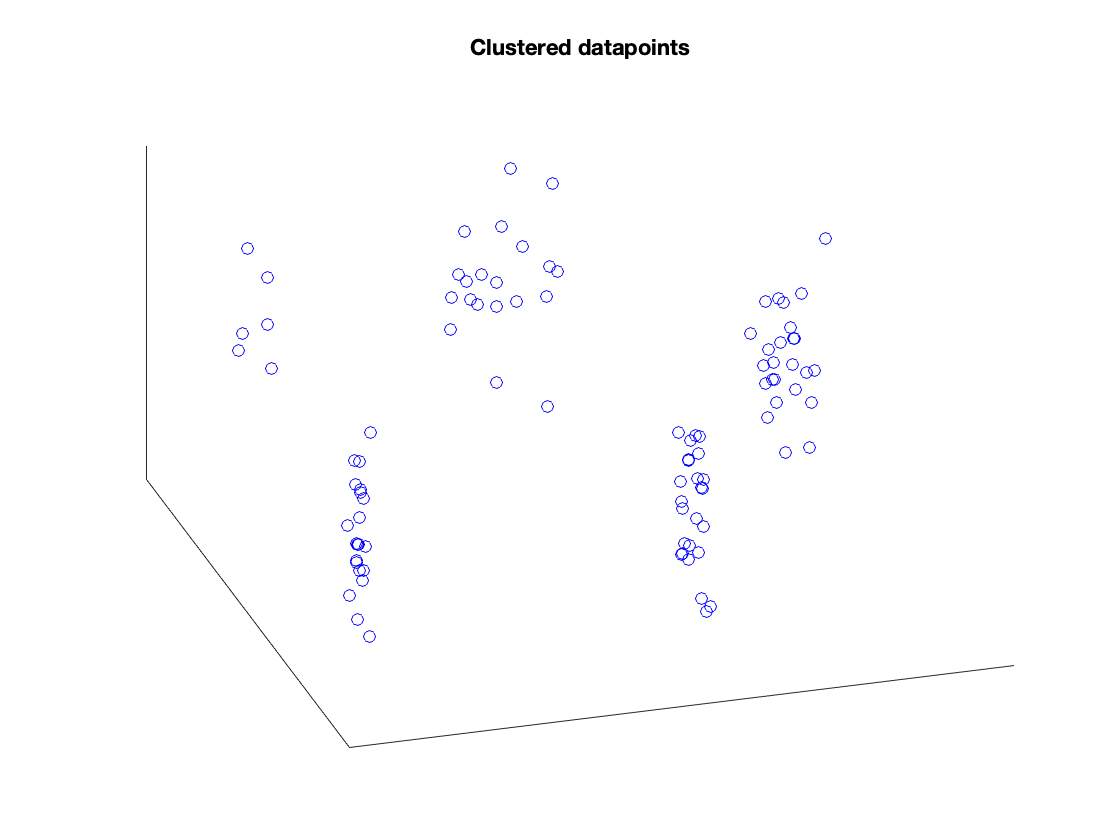

% visualize the original clusters
figure(1)
plot3(X(1,:),X(2,:),X(3,:),'ob')
set(gca,'XTick',[])
set(gca,'YTick',[])
set(gca,'ZTick',[])
title('Clustered datapoints')
view([-17 40])

## Single-linkage clustering

% naive implementation of the single-linkage algorithm
partition_sl = eye(m);                                         % its columns will hold the clusters
for t=0:m-k-1
    d = inf(m-t,m-t);                                          % matrix of distances between clusters
    for i=1:m-t-1
        C_i = find(partition_sl(:,i));
        for j=i+1:m-t
            C_j = find(partition_sl(:,j));
            dist_ij = min(min(dist(C_i,C_j)));                 % distance between clusters C_i and C_j
            d(i,j) = dist_ij;
            d(j,i) = dist_ij;
        end
    end
    [~,j] = min(min(d));
    [~,i] = min(d(:,j));
    partition_sl(:,i) = partition_sl(:,i)+partition_sl(:,j);   % merge C_i and C_j
    partition_sl(:,j) = [];                                    % remove C_j
end

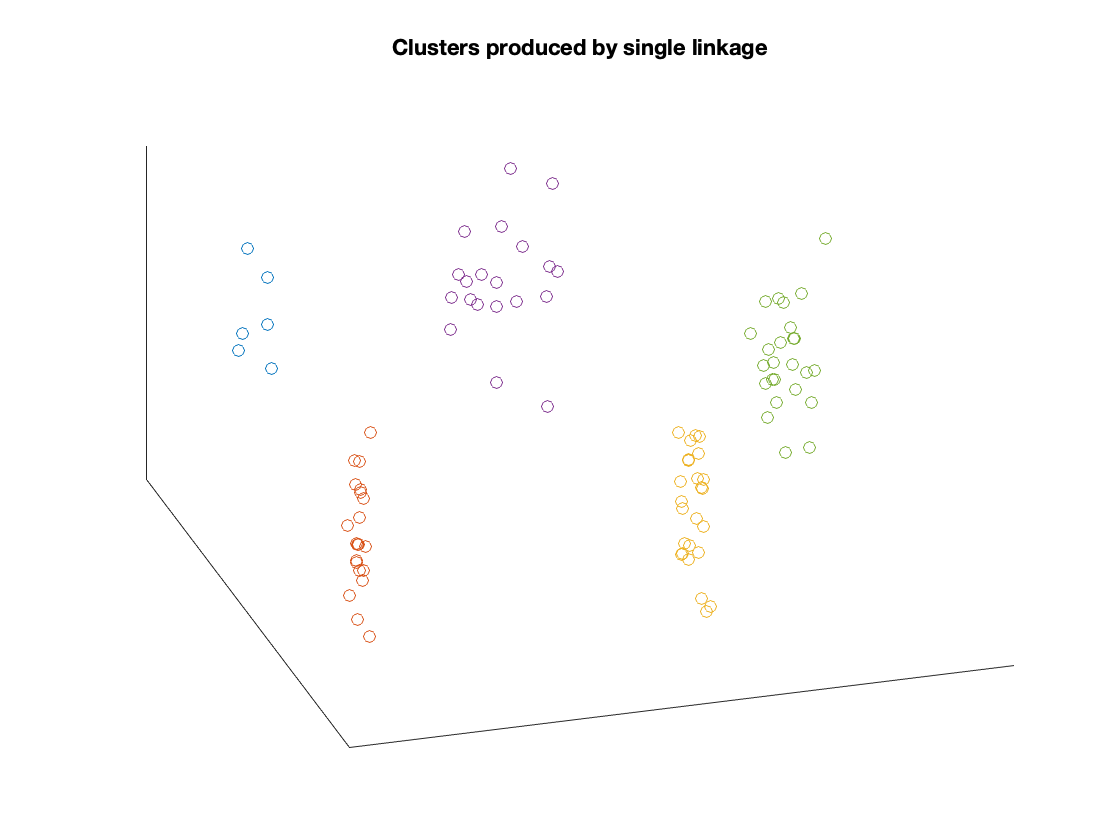

% visualize the ouputted clusters
figure(2)
for h=1:k
    C_h = find(partition_sl(:,h));
    plot3(X(1,C_h),X(2,C_h),X(3,C_h),'o'); 
    hold on
end
set(gca,'XTick',[])
set(gca,'YTick',[])
set(gca,'ZTick',[])
title('Clusters produced by single linkage')
view([-17 40])

## Center-based clustering -- Lloyd algorithm

% naive implementation of Lloyd algorithm
centers = [4*rand(2,k)-2; zeros(1,k)];                  
partition_Lloyd = zeros(m,k);                               
n_iters = 100;                                       
for t=1:n_iters
    dist = zeros(k,m);                   
    for h=1:k
       for i=1:m
           dist(h,i) = norm(X(:,i)-centers(:,h));
       end 
    end
    [~,aux] = min(dist);
    for h=1:k
        C_h = find(aux==h);                              
        partition_Lloyd(:,h) = (aux==h);                     
        if length(C_h) > 0
            centers(:,h) = sum(X(:,C_h),2)/length(C_h);  
        end
   end
end

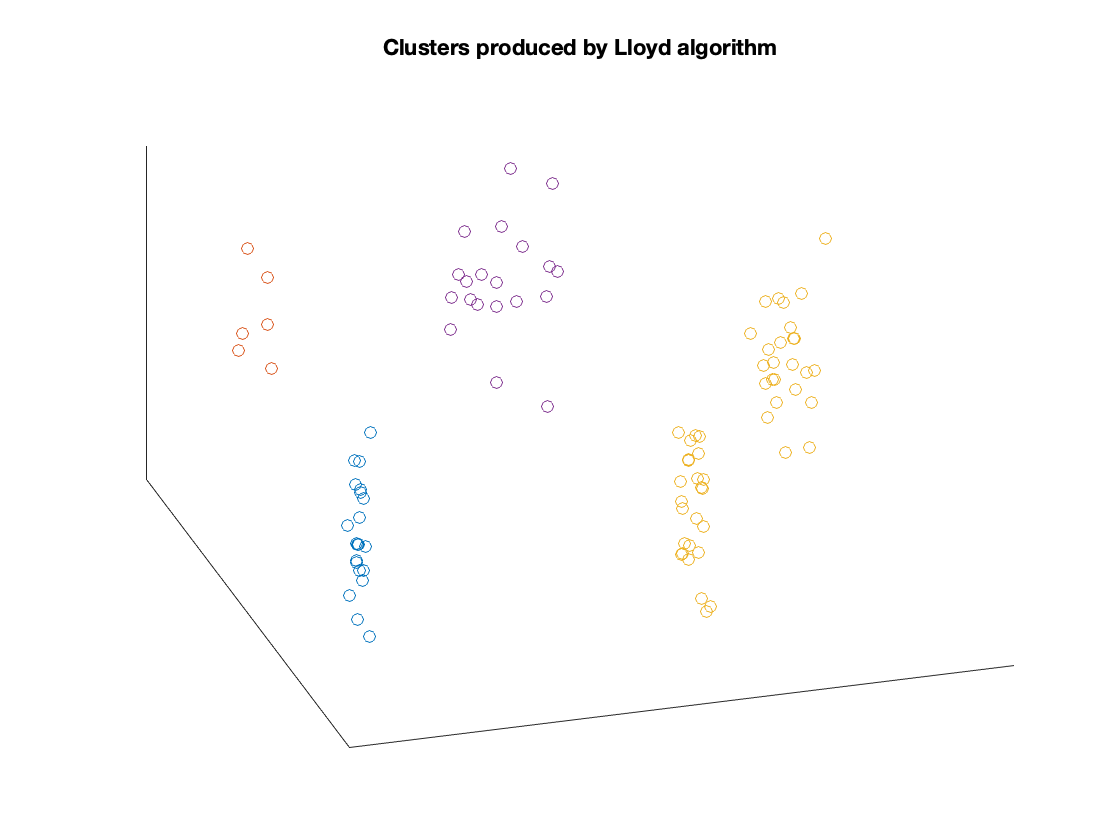

% visualize the ouputted clusters
figure(3)
view(3)
for h=1:k
    C_h = find(partition_Lloyd(:,h));
    plot3(X(1,C_h),X(2,C_h),X(3,C_h),'o'); 
    hold on
end
set(gca,'XTick',[])
set(gca,'YTick',[])
set(gca,'ZTick',[])
title('Clusters produced by Lloyd algorithm')
view([-17 40])

## Spectral clustering

The function producing two communities and the adjacency matrix generated by the stochastic block model is defined at the end of the document.

% choose the parameters
m = 500;
p = 1/4;
q = 3/4;
[comm1,comm2,W] = stochastic_block_model_generator(m,p,q);

% Clustering according to the leading eigenvector of W - omega*ones(m,m)
omega = sum(sum(W))/m^2;
[V,~] = eigs(W-omega*ones(m,m),1,'largestreal');
c_sp1 = find(V(:,1)>0)';
c_sp2 = find(V(:,1)<=0)';
% determine the percentage of errors made
n1 = length(intersect(comm1,c_sp1))+length(intersect(comm2,c_sp2));
n2 = length(intersect(comm1,c_sp2))+length(intersect(comm2,c_sp1));
fprintf(strcat('Percentage of errors:', 32, num2str(100*min(n1,n2)/m),37,'%'))

Percentage of errors: 0%

There seems to be no errors at all when m is large enough!

## Empirical estimation of the error percentage depending on m, p, and q

close all; clear all;
% parameters for the range of values of m to be tested
m_min = 4;
m_max = 140;
m_inc = 4;
% number of random trials performed for a given m
nb_trials = 50;
% fix one value of q and consider several values of p
q = 3/4;
p_values = [1/10, 1/5, 1/4, 1/2];
% matrix to store the percentage of errors
perc_errors = zeros( 1+(m_max-m_min)/m_inc ,length(p_values) );
% loop reproducing the above code
for j=1:length(p_values)
    for m = m_min:m_inc:m_max
        err = 0;
        for t=1:nb_trials            
            [comm1,comm2,W] = stochastic_block_model_generator(m,p_values(j),q);
            omega = sum(sum(W))/m^2;
            [V,~] = eigs(W-omega*ones(m,m),1,'largestreal');
            c_sp1 = find(V(:,1)>0)';
            c_sp2 = find(V(:,1)<=0)';
            n1 = length(intersect(comm1,c_sp1))+length(intersect(comm2,c_sp2));
            n2 = length(intersect(comm1,c_sp2))+length(intersect(comm2,c_sp1));
            err = err + min(n1,n2);
        perc_errors(1+ (m-m_min)/m_inc,j) = 100*err/(m*nb_trials);
        end
    end
end

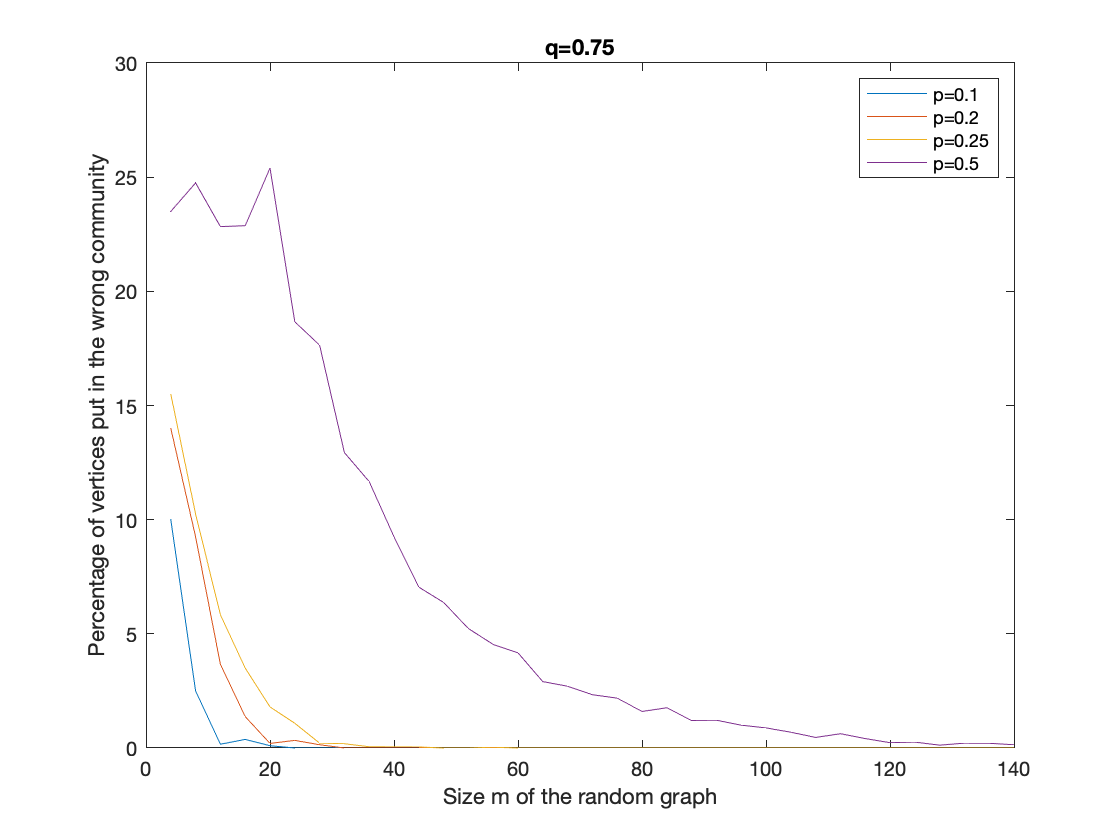

% visualize the results
figure(4)
for j=1:length(p_values)
    plot(m_min:m_inc:m_max,perc_errors(:,j));
    hold on
end
title(strcat('q=',num2str(q)));
xlabel('Size m of the random graph');
ylabel('Percentage of vertices put in the wrong community');
legend(strcat('p=',num2str(p_values(1))),...
    strcat('p=',num2str(p_values(2))),...
    strcat('p=',num2str(p_values(3))),...
    strcat('p=',num2str(p_values(4))));

Here is a function producing two communities and the adjacency matrix generated by the stochastic block model.

function [comm1,comm2,W] = stochastic_block_model_generator(m,p,q)
perm = randperm(m);
comm1 = sort(perm(1:m/2));                     % indices of members of the first community
comm2 = sort(perm(m/2+1:m));                   % indices of members of the second community
% define an auxiliary 0/1-matrix whose entries = 1 w.proba p
aux1 = (rand(m/2,m/2)<p);
% define an auxiliary 0/1-matrix whose entries = 1 w.proba q
aux2 = (rand(m/2,m/2)<q);   
aux2l = tril(aux2) - diag(diag(aux2));         % lower triangular part without the diagonal
aux2u = triu(aux2) - diag(diag(aux2));         % upper triangular part without the diagonal
% define the random adjacency matrix W
W = zeros(m,m);
W(comm1,comm1) = aux2l+aux2l';
W(comm1,comm2) = aux1;
W(comm2,comm1) = aux1';
W(comm2,comm2) = aux2u+aux2u';
end